Identifikovane polynomy

pGain = [-7.74558355399971e-09 7.92523655765039e-06 -0.00291980737503381 0.463728547328537 -23.1386227555553];
pT = [1.10661505286941e-07 -5.48243874702451e-05 0.00740611980939077 -0.00882197108389277];
p = [1.27264127791514e-06,-0.000693202019254355,0.101241610731183,5.53942212609170,-881.974593934446];
pK = [6.06868337517324e-06,-0.00276839370282041,0.349669070323109,-3.90147463042572];

Urcenie parametrov v pracovnom bode

%parametre odcitane z pracovneho bodu
upb = 206

upb = 206

ypb = polyval(pGain,upb)*upb

ypb = 786.3259

T = polyval(pT,upb)

T = 0.1577

K = polyval(pK,upb)

K = 3.7021


a0 = 1/T

a0 = 6.3414

b0 = K/T

b0 = 23.4766

Referencny model

am = 10;
bm = 10;

Urcenie parametrov zakona riadenia (P regulator)

theta1_ideal = (a0-am)/b0

theta1_ideal = -0.1558

theta2_ideal = bm/b0

theta2_ideal = 0.4260

Simulacia a vykreslenie

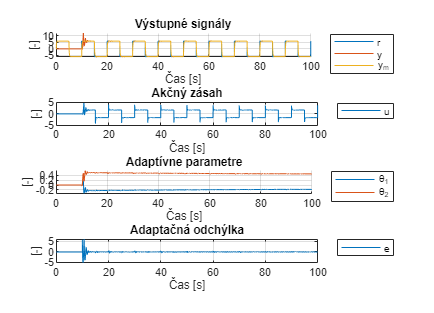

clf;
alpha = 0.7;
out = sim('MRAC_MIT_regulator.slx');

figure;
subplot(4,1,1);
hold on;
plot(out.tout,out.r.Data,'DisplayName','r');
plot(out.tout,out.y.Data,'DisplayName','y');
plot(out.tout,out.ym.Data,'DisplayName','y_m');
hold off;
xlabel('Čas [s]');ylabel('[-]');grid on; title('Výstupné signály');legend('Location',"bestoutside");
%ylim([0,20])


subplot(4,1,2);
plot(out.tout,out.u.Data,'DisplayName','u');
xlabel('Čas [s]');ylabel('[-]');grid on; title('Akčný zásah');legend('Location',"bestoutside");

subplot(4,1,3);
hold on;
plot(out.tout,out.theta1.Data,'DisplayName','\theta_1');
plot(out.tout,out.theta2.Data,'DisplayName','\theta_2');
hold off;
xlabel('Čas [s]');ylabel('[-]');grid on; title('Adaptívne parametre');legend('Location',"bestoutside");

subplot(4,1,4);
plot(out.tout,out.e.Data,'DisplayName','e');
xlabel('Čas [s]');ylabel('[-]');grid on; title('Adaptačná odchýlka');legend('Location',"bestoutside");